Hago un modelo FOPDT con los datos extraídos de la simulación del proteus, idealmente cuando tenga la placa voy a tener que hacerlo con los datos reales. Pero por el momento para implementar el PID sirve.

clc; clear all;
s=tf('s');
z=tf('z');

Cargo los datos del proteus

data_proteus = importdata('step_response_voltage.DAT')

data_proteus = struct with fields:
          data: [22580×4 double]
      textdata: {'"TIME"'  '"PB4"'  '"readV"'  '"Vnode"'}
    colheaders: {'"TIME"'  '"PB4"'  '"readV"'  '"Vnode"'}



time = data_proteus.data(:, 1)

time =          0
    0.0020
    0.0040
    0.0080
    0.0160
    0.0320
    0.0640
    0.0650
    0.0650
    0.0650


y = data_proteus.data(:, 3)

y =     0.4571
    0.4571
    0.4571
    0.4571
    0.4571
    0.4571
    0.4571
    0.4571
    0.4571
    0.4571


pb4 = data_proteus.data(:, 2)

pb4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


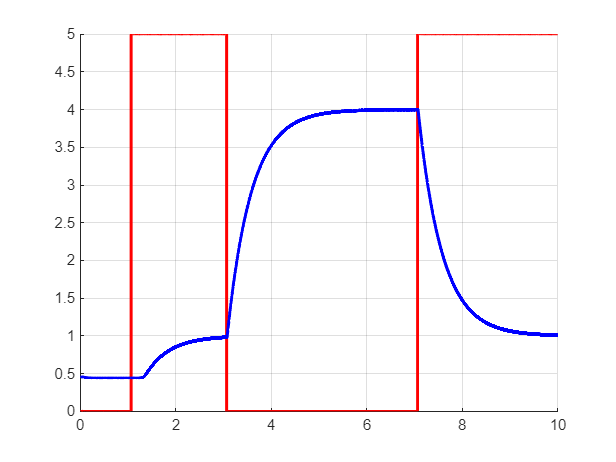

figure();
hold on; grid on;

plot(time, pb4, 'r', 'LineWidth', 2);
plot(time, y, 'b', 'LineWidth', 2);

Arreglo para quedarme con el escalón de subida y el de bajada

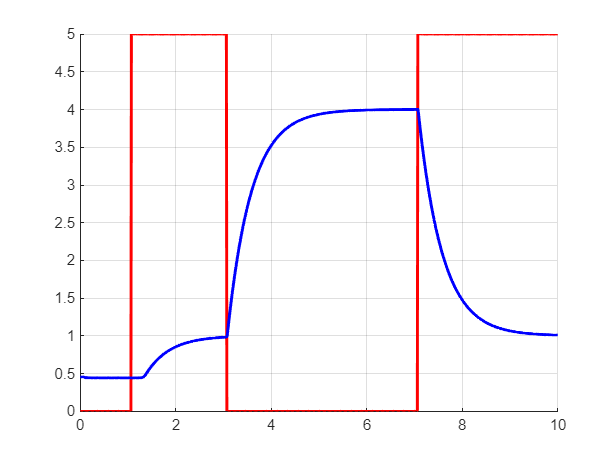

Ts=10e-3;
linear_time = 0:Ts:10;
linear_y = interp1(time, y, linear_time);
linear_pb4 = interp1(time, pb4, linear_time);

figure();
hold on; grid on;

plot(linear_time, linear_pb4, 'r', 'LineWidth', 2);
plot(linear_time, linear_y, 'b', 'LineWidth', 2);

Me quedo con el escalón de subida

starting_index = find(linear_pb4 > 2.5, 1, 'first')

starting_index = 108

step_up_start = find(linear_pb4(starting_index:end) < 2.5, 1, 'first') + starting_index - 2

step_up_start = 307

step_up_end = find(linear_pb4(starting_index:end) < 2.5, 1, 'last') + starting_index - 1

step_up_end = 707

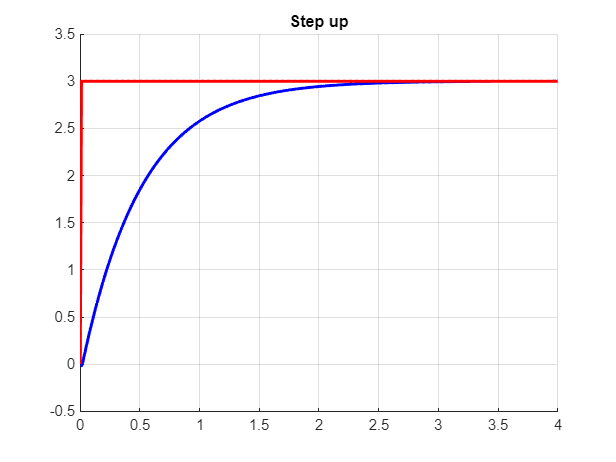


step_up_resp = linear_y(step_up_start:step_up_end)-1;
step_up_time = linear_time(step_up_start:step_up_end)-linear_time(step_up_start);
step_up = 3*ones(1, length(step_up_resp)); step_up(1) = 0;

figure();
hold on; grid on;
title('Step up');

plot(step_up_time, step_up_resp, 'b', 'LineWidth', 2);
plot(step_up_time, step_up, 'r', 'LineWidth', 2);

Ahora hago lo mismo pero para el escalón de bajada

step_down_start = find(linear_pb4 < 2.5, 1, 'last')

step_down_start = 707

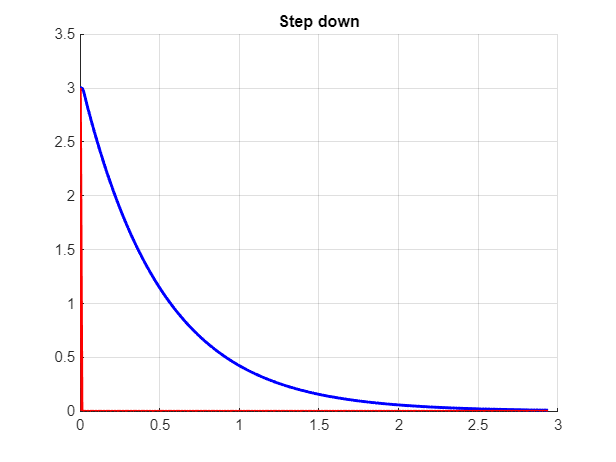


step_down_resp = linear_y(step_down_start:end)-1;
step_down_time = linear_time(step_down_start:end)-linear_time(step_down_start);
step_down = zeros(1, length(step_down_resp)); step_down(1) = 3;

figure();
hold on; grid on;
title('Step down');

plot(step_down_time, step_down_resp, 'b', 'LineWidth', 2);
plot(step_down_time, step_down, 'r', 'LineWidth', 2);

Modelo FOPDT resultante:

Kp=1.0008;
Tp1 = 0.50197;
Td = 0.00503;

Gs = Kp/(1+Tp1*s);
Gs.InputDelay = Td


Gs =
 
                       1.001
  exp(-0.00503*s) * -----------
                    0.502 s + 1
 
Continuous-time transfer function.
Model Properties


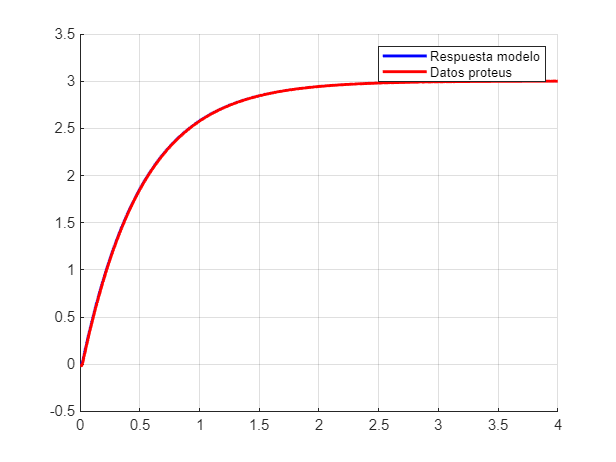

Gs_discrete = c2d(Gs, Ts);
[G_A, G_B, G_C, G_D] = tf2ss(Gs_discrete.Numerator{1}, Gs_discrete.Denominator{1});

[model_resp, ~] = lsim(Gs, step_up, step_up_time);

figure();
hold on; grid on;

plot(step_up_time, model_resp, 'b', 'LineWidth', 2);
plot(step_up_time, step_up_resp, 'r', 'LineWidth', 2);

legend('Respuesta modelo', 'Datos proteus');

Diseño el controlador basandome en el modelo FOPDT.

Voy a cancelar el polo con un cero  de mi controlador y voy a setear un polo con ganancia para ajustar la dinámica para que sea más rápida

T0 = Tp1*0.1;
C = (s*Tp1+1)/(s*T0+1)


C =
 
  0.502 s + 1
  ------------
  0.0502 s + 1
 
Continuous-time transfer function.
Model Properties



CL_SYSTEM = Gs*C/(1+Gs*C)


CL_SYSTEM =
 
  A = 
           x1      x2      x3      x4      x5
   x1  -21.91  -4.961       0       0       4
   x2       8       0       0       0       0
   x3       0       0  -21.91  -4.961       4
   x4       0       0       8       0       0
   x5       0       0   4.984   1.241       1
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   0
   x5  -1
 
  C = 
          x1     x2     x3     x4     x5
   y1  4.984  1.241      0      0      0
 
  D = 
       u1
   y1   0
 
  E = 
       x1  x2  x3  x4  x5
   x1   1   0   0   0   0
   x2   0   1   0   0   0
   x3   0   0   1   0   0
   x4   0   0   0   1   0
   x5   0   0   0   0   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.00503  0.00503 
 
Continuous-time state-space model.


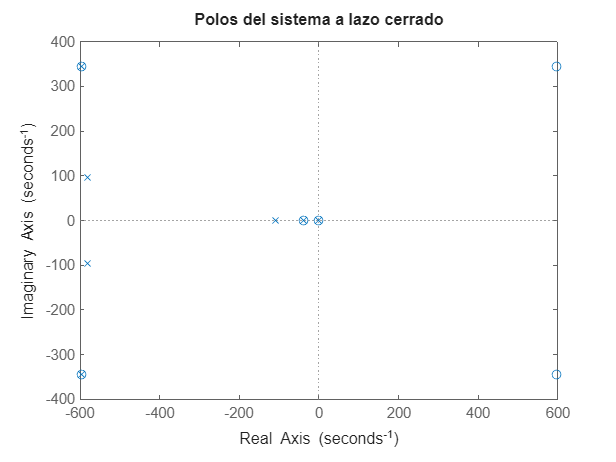

CL_SYSTEM_PADE=pade(CL_SYSTEM, 2);

figure();
pzmap(CL_SYSTEM_PADE);
title('Polos del sistema a lazo cerrado');

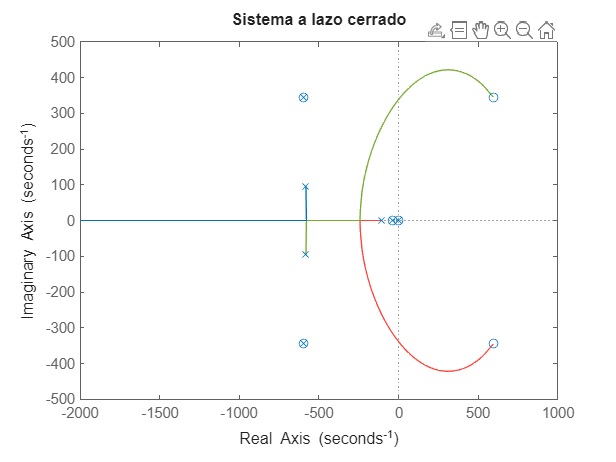


figure();
rlocus(CL_SYSTEM_PADE);
title('Sistema a lazo cerrado');

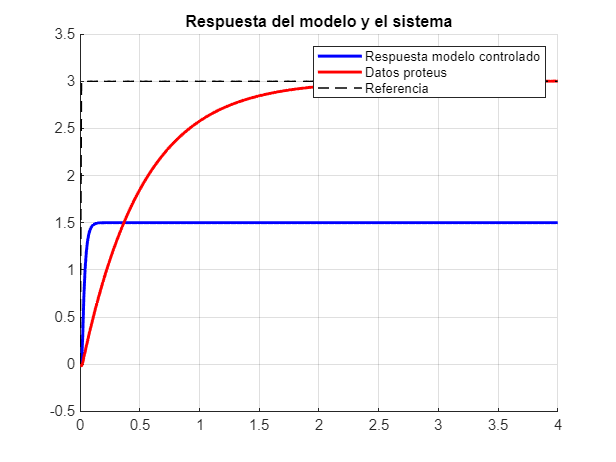


[c_step_resp, ~] = lsim(CL_SYSTEM, step_up, step_up_time);

gain_net = c_step_resp(end);
REFERENCE_GAIN=3/(gain_net);

figure();
hold on; grid on;
title('Respuesta del modelo y el sistema')

plot(step_up_time, c_step_resp, 'b', 'LineWidth', 2);
plot(step_up_time, step_up_resp, 'r', 'LineWidth', 2);
plot(step_up_time, step_up, '--k', 'LineWidth', 1);

legend('Respuesta modelo controlado', 'Datos proteus', 'Referencia');

Discretizo y lo paso a esc en diferencias para calcular las ganancias

C_discrete = c2d(C, Ts)


C_discrete =
 
  10 z - 9.819
  ------------
   z - 0.8194
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


[Cnum, Cden] = tfdata(C_discrete, 'v')

Cnum =    10.0000   -9.8194


Cden =     1.0000   -0.8194



SCALE_FACTOR = 1e3;
voltage_e_gains = (Cnum)

voltage_e_gains =    10.0000   -9.8194


voltage_u_gain = -Cden(2)

voltage_u_gain = 0.8194

Guardo en un archivo .h las ganancias del controlador

filename='codigo/include/voltage_controller.h';
fid = fopen(filename, 'w');
if fid == -1
    error('Error opening the file: %s', filename);
end

guard = upper(strrep('PID.h', '.', '_'));
fprintf(fid, '#ifndef %s\n#define %s\n\n', guard, guard);

% fprintf(fid, "#define SCALE_FACTOR (%d)\n", SCALE_FACTOR);

for i=1:length(voltage_e_gains)
    fprintf(fid, "#define VOLTAGE_E_GAIN_%d (%ff)\n", i, voltage_e_gains(i));
end
fprintf(fid, "#define VOLTAGE_U_GAIN (%ff)\n\n\n", voltage_u_gain);
fprintf(fid, "#define REFERENCE_GAIN (%ff)\n\n\n", REFERENCE_GAIN);

fprintf(fid, '#endif // %s\n', guard);

fclose(fid);

Simulación del controlador en el tiempo, para ver que las ganancias están correctamente implementadas y no hay error en el microcontrolador (osea el código en C)

time_vector = 0:Ts:5;

states = zeros(length(G_A), 1);
ref = 1.5;
reference = ref*ones(1, length(time_vector));
% perturbance=zeros(1, length(time_vector));perturbance(round(length(perturbance)*0.5):end)=0.2*ref;
% reference=reference-perturbance;
y = zeros(1, length(time_vector));
u = zeros(1, length(time_vector));

% e_gains
% u_gains

fprintf("(%f)e[n] + (%f)e[n-1] + (%f)u[n-1]\n", voltage_e_gains(1), voltage_e_gains(2), voltage_u_gain)

(10.000000)e[n] + (-9.819374)e[n-1] + (0.819374)u[n-1]


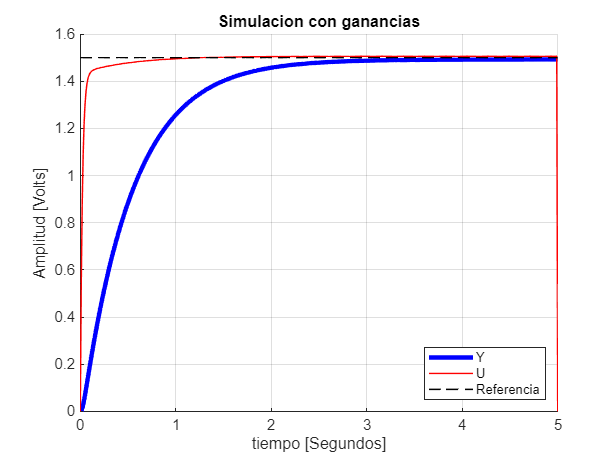


for i = 2:(length(time_vector)-1)

    e0 = REFERENCE_GAIN*reference(i) - y(i);
    e1 = REFERENCE_GAIN*reference(i-1) - y(i-1);
    u1 = u(i-1);

    u(i) = (voltage_e_gains(2)*e1 + voltage_e_gains(1)*e0 + voltage_u_gain*u1);

    % if (u(i) > 5)
    %     u(i) = 5;
    % elseif (u(i) < 0)
    %     u(i) = 0;
    % end

    states = G_A*states + G_B*u(i);
    y(i+1) = G_C*states;

end

% y
% u

figure; hold on; grid on;
plot(time_vector, y, 'b', 'LineWidth', 3);
plot(time_vector, u, 'r', 'LineWidth', 1);
plot(time_vector, reference, '--k', 'LineWidth', 1);

title('Simulacion con ganancias');
ylabel('Amplitud [Volts]');
xlabel('tiempo [Segundos]');
legend('Y', 'U', 'Referencia', 'Location', 'southeast');